What we do here is:

- Calculate the exact rate.

- KKT condiotions solution.

clc
close all
addpath('C:\Users\Asus irG\OneDrive\Documents\MATLAB\Thesis numerical analysis\RIS-Sharing-Scenario-main\common methods') % You need to change the address in case you run it on your computer

%% parameters
N1 = 3 ;
R1 = 10 ;                                % BS1 user area center radius
R2 = 10 ;                                % BS2 user area center radius    
N = 20 ;                                % No.  IRS elements
P_T = (10^(40/10)) * 1e-3 ;                 % BS power
% [x0 , y0 , z0] = deal(50 , 20 , 0) ;              % user area center
[x1 , y1 , z1] = deal(0 , 0 , 0) ;                % BS1 location
[x2 , y2 , z2] = deal(100 , 10 , 0) ;             % BS2 location
[x_i , y_i , z_i] = deal(50 , 30 , 10) ;          % IRS location
M_t = 1 ;                                 % No. of transmitter antennas
M_r = 1 ;                                 % No. of receiver antennas
d_IB = 100 ; 
alpha_d = 3.76 ; 
alpha_r = 2 ; 
BW = 10e7 ; 
noise_power = (10^(-114/10)) ;            % -169dbm/Hz
epsilon = 0.05 ;

%% users location
x = zeros(N1 , 1) ; 
y = zeros(N1 , 1) ; 
z = 1.5 * ones(N1, 1) ; 
x(1 : N1 , 1) = 35 ; 
y(1 : N1 , 1) = 25 ; 
epsilon = 0.01 ;

## Calculate the rates

t = 2 * pi * rand(N1,1) ;
R=[10 10] ;
radius  =  R(1) * sqrt(rand(N1,1)) ;
x0(1 : N1 , 1) = 35 ; 
y0(1 : N1 , 1) = 25 ;
x(1 : N1) = x0(1 : N1)  +  radius.* cos(t) ;
y(1 : N1) = y0(1 : N1)  +  radius.* sin(t)  ;
h_d = (10^0.2) * (randn(N1 , M_t , M_r) + 1j * randn(N1 , M_t , M_r)) * sqrt(1/2).* ((10^0.2)./(sqrt( (x(1:N1)-x1).^2 + (y(1:N1)-y1).^2 + (z(1:N1)-z1).^2 )).^alpha_d) ;
g = (10^0.2) * (randn(N , M_t , M_r) + 1j * randn(N , M_t , M_r)) * sqrt(1/2).* ((10^0.2)./(sqrt( (x_i-x1).^2 + (y_i-y1).^2 + (z_i-z1).^2 )).^alpha_r) ;
h_r = zeros(N , N1) ;
for j = 1 : N1
    h_r( :  , j) = (10^0.2) * (randn(N , M_t , M_r) + 1j * randn(N , M_t , M_r)) * sqrt(1/2).* ((10^0.2)./(sqrt( (x(j)-x_i).^2 + (y(j)-y_i).^2 + (z(j)-z_i).^2 )).^alpha_r) ;
end
[~ ,  Z_cvx1] = Rate2(h_d ,  g ,  h_r ,  N1 ,  N ,  P_T ,  noise_power ,  N_iter) ;
Theta = diag(Z_cvx1) ;
channel_gain = sort(abs(h_d + h_r'  *  Theta  *  g)) ;
channel_gain = channel_gain.^2  *  P_T / noise_power ;
% channel_gain = channel_gain * 1e2 ;
[exact_rate, b_star] = SISONoma(epsilon, channel_gain) 

exact_rate = 5.4416

b_star =     1.0000
    0.0233
    0.0005
         0


## KKT condition Solution

As you can see all three rate are equal.

q_star = (channel_gain(1) - channel_gain(2) +...
    sqrt( (channel_gain(1) - channel_gain(2))^2 +...
    4*channel_gain(1)*(channel_gain(2) +...
    channel_gain(1)*channel_gain(2)) ))/2/channel_gain(1) ;

b(2) = (q_star - 1)/channel_gain(2) ;
b(2) = (1 + channel_gain(1) - q_star)/channel_gain(1)/q_star ;
b(1) = 1 ;
exact_rate1 = log2(1 + ((b(1) - b(2)) * channel_gain(1))/(1 + b(2) * channel_gain(1))) ;
exact_rate21 = log2(1 + ((b(1) - b(2)) * channel_gain(2))/(1 + b(2) * channel_gain(2))) ;
exact_rate22 = log2(1 + (b(2) * channel_gain(2))) ;

## N>2 

The method suggested by that paper 

D=$diag \{ \frac{1}{|h_1|^2},\cdots,\frac{1}{|h_{N_1}|^2}\}$

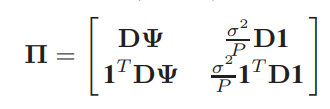


$$[\Psi]_{ik} = |h_i|^2 \quad for\quad
 i<k$$


% channel_gain = sort(abs(h_d + h_r'  *  Theta  *  g)).^2 ;
channel_gain = [0.25 ; 0.5] ;
noise_power = 0.1 ;
P_T = 10 ;
N1 = 2 ;
Sai = zeros(N1,N1);
for i = 1 : N1
    Sai(i , i + 1 : end) = channel_gain(i) ;
end
D = diag(1./channel_gain) ;
Pai=[D*Sai , noise_power/P_T*D*ones(N1,1);...
    ones(N1,1)'*D*Sai , noise_power/P_T*ones(N1,1)'*D*ones(N1,1)] ;
[U , A , V] = svd(Pai) ;
disp(1/(A(1)))

    0.7062



disp(U(:,1)/U(end,1))

    0.9990
    0.0010
    1.0000



(0.762*0.25)/(0.238*0.25+0.1)

ans = 1.1944

0.238*0.5/0.1

ans = 1.1900